Составление уравнений состояния цепи второго порядка

Метод узловых напряжений

syms u0 i0 il uc p;
syms r1 r2 r3 c l rn

Параметры в условии

% r1 = 500;
% r2 = 12000;
% r3 = 500;
% rn = 1000;
% c = 0.05*10^(-6);
% l = 0.1;

Нормированные параметры

r1 = 1;
r2 = 24;
r3 = 1;
rn = 2;
c = 1;
l = 8;

Матрица кэффициентов А

m11 = -(r1+r2)/(c*((r3+rn)*(r1+r2)+r1*r2))

m11 = -0.2525

m12 = (r3*(r1+r2)+r1*r2)/(((rn+r3)*(r1+r2)+r1*r2)*c)

m12 = 0.4949

m21 = -(r3*(r1+r2)+r1*r2)/(l*((r3+rn)*(r1+r2)+r1*r2))

m21 = -0.0619

m22 = -(r3*rn*(r1+r2)+rn*r1*r2)/(l*((r3+rn)*(r1+r2)+r1*r2))

m22 = -0.1237

M = [m11, m12; m21, m22]

M =    -0.2525    0.4949
   -0.0619   -0.1237


M-eye(2, 2)*p

$$ans = \left(\begin{array}{cc} -p-\frac{25}{99} & \frac{49}{99}\\ -\frac{49}{792} & -p-\frac{49}{396} \end{array}\right)$$

eqn = det(M-eye(2, 2)*p)

$$eqn = p^{2}+\frac{149\,p}{396}+\frac{49}{792}$$

Нормированный ответ

p12 = solve(eqn == 0, p)

$$p12 = \left(\begin{array}{c} -\frac{149}{792}-\frac{\sqrt{16607}\,\mathrm{i}}{792}\\ -\frac{149}{792}+\frac{\sqrt{16607}\,\mathrm{i}}{792} \end{array}\right)$$

Ненормированный ответ

solve(eqn == 0, p)/25/10^(-6)

$$ans = \left(\begin{array}{c} -\frac{745000}{99}-\frac{5000\,\sqrt{16607}\,\mathrm{i}}{99}\\ -\frac{745000}{99}+\frac{5000\,\sqrt{16607}\,\mathrm{i}}{99} \end{array}\right)$$

% M = [-3/11-p, 5/11; -5/(11*8), -10/(11*8)-p]
%eqn = det(M)

% A1 = [-3/11, 5/11; -5/(11*8), -10/(11*8)]
% A2 = [uc; il]
% A1*A2


Определение коэффициентов общего решения уравнений состояния

syms ut it t alpha beta
alpha = real(p12(2))

$$alpha = -\frac{149}{792}$$

beta = imag(p12(2))

$$beta = \frac{\sqrt{16607}}{792}$$

du0_c = 56/99;
di0_l = 86/(99*8);
ui_c = 2;
ii_l = 144/49;
u0_c = 0;
i0_l = 144/49;
A1 = -2

A1 = -2

A2 = 1/beta*(du0_c-alpha*A1)

$$A2 = \frac{150\,\sqrt{16607}}{16607}$$

ut = exp(alpha*t)*(A1*cos(beta*t)+A2*sin(beta*t))+ui_c;
vpa(ut, 6)

$$ans = 2.0-1.0\,{\mathrm{e}}^{-0.188131\,t}\,\left(2.0\,\cos\left(0.162712\,t\right)-1.16398\,\sin\left(0.162712\,t\right)\right)$$

B1 = 0

B1 = 0

B2 = 1/beta*(di0_l-alpha*B1);
vpa(B2, 4)

$$ans = 0.6673$$

it = exp(alpha*t)*(B1*cos(beta*t)+B2*sin(beta*t))+ii_l;
vpa(it, 4)

$$ans = 0.6673\,{\mathrm{e}}^{-0.1881\,t}\,\sin\left(0.1627\,t\right)+2.939$$

tau = -1/real(p12(1))

$$tau = \frac{792}{149}$$

% fplot([ut it])
% xlim([0, 50])
% grid on
% hold off

Построение решений уравнений состояния методом Эйлера

syms fu fi u_c i_l
%Шаг численного метода
dt = 0.1;
%Правый край исследуемого интервала
T = 25;
%Значения тока ИТ и напряжения ИН
u_0 = 6;
i_0 = 1;
%Предначальные условия
u0_c = 0;
i0_l = 144/49;
%Уравнение состояния напряжения C-элемента
fu = -25/99*u_c+49/99*i_l-24/99*u_0+50/99*i_0

$$fu = \frac{49\,i_{l}}{99}-\frac{25\,u_{c}}{99}-\frac{94}{99}$$

%Уравнение состояния напряжения L-элемента
fi = -49/(99*8)*u_c-98/(99*8)*i_l+48/(99*8)*u_0+98/(99*8)*i_0

$$fi = \frac{193}{396}-\frac{49\,u_{c}}{792}-\frac{49\,i_{l}}{396}$$

%Реализация метода Эйлера
ut_e = zeros(1, floor(T/dt)+1);
it_e = zeros(1, floor(T/dt)+1);
ut_e(1) = u0_c;
it_e(1) = i0_l;
i = 2;
%subs(выражение, заменяемая ппеременная, подставляемое значение)
while (i <= length(it_e))
    ut_e(i) = ut_e(i-1)+dt*subs(fu, [u_c i_l], [ut_e(i-1) it_e(i-1)]);
    it_e(i) = it_e(i-1)+dt*subs(fi, [u_c i_l], [ut_e(i-1) it_e(i-1)]);
    i = i+1;
end
ut_e

ut_e =          0    0.0505    0.1003    0.1495    0.1980    0.2458    0.2930    0.3394    0.3852    0.4302    0.4746    0.5183    0.5612    0.6035    0.6451    0.6859    0.7261    0.7656    0.8043    0.8424    0.8798    0.9165    0.9525    0.9878    1.0225    1.0564    1.0897    1.1223    1.1543    1.1856    1.2162    1.2462    1.2756    1.3043    1.3324    1.3598    1.3866    1.4129    1.4385    1.4635    1.4879    1.5117    1.5350    1.5577    1.5798    1.6013    1.6224    1.6428    1.6627    1.6821


it_e

it_e =     2.9388    2.9511    2.9631    2.9745    2.9855    2.9961    3.0062    3.0160    3.0253    3.0342    3.0427    3.0509    3.0587    3.0661    3.0731    3.0799    3.0862    3.0923    3.0980    3.1035    3.1086    3.1134    3.1180    3.1222    3.1262    3.1299    3.1334    3.1366    3.1396    3.1424    3.1449    3.1472    3.1493    3.1512    3.1528    3.1543    3.1556    3.1567    3.1577    3.1584    3.1590    3.1595    3.1598    3.1599    3.1599    3.1598    3.1595    3.1591    3.1586    3.1579


Графики точного и численного решения уравнений состояния

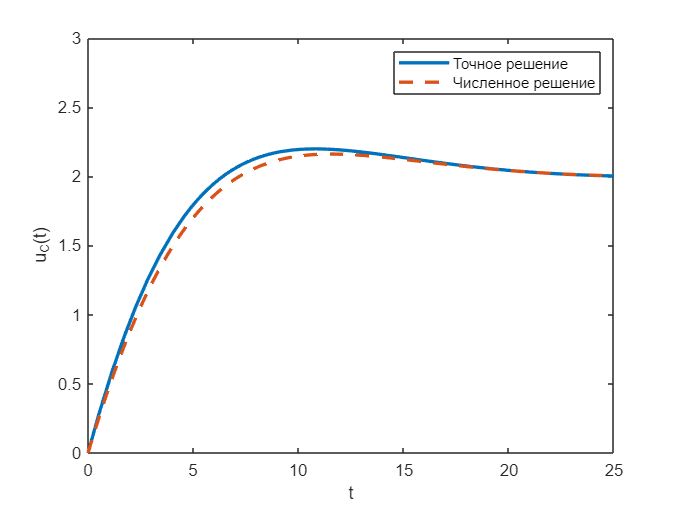

xs = 0:dt:T;
fplot(ut, 'linewidth', 2)
hold on
plot(xs, ut_e, '--', 'linewidth', 2)
xlim([0, 25])
ylim([0, 3])
legend("Точное решение", "Численное решение")
%title("Решение уравнения состояния для С-элемента")
xlabel('t')
ylabel('u_C(t)')
hold off

ut = vpa(ut, 4)

$$ut = 2.0-1.0\,{\mathrm{e}}^{-0.1881\,t}\,\left(2.0\,\cos\left(0.1627\,t\right)-1.164\,\sin\left(0.1627\,t\right)\right)$$

ut_e

ut_e =          0    0.0505    0.1003    0.1495    0.1980    0.2458    0.2930    0.3394    0.3852    0.4302    0.4746    0.5183    0.5612    0.6035    0.6451    0.6859    0.7261    0.7656    0.8043    0.8424    0.8798    0.9165    0.9525    0.9878    1.0225    1.0564    1.0897    1.1223    1.1543    1.1856    1.2162    1.2462    1.2756    1.3043    1.3324    1.3598    1.3866    1.4129    1.4385    1.4635    1.4879    1.5117    1.5350    1.5577    1.5798    1.6013    1.6224    1.6428    1.6627    1.6821


it = vpa(it, 4)

$$it = 0.6673\,{\mathrm{e}}^{-0.1881\,t}\,\sin\left(0.1627\,t\right)+2.939$$

it_e

it_e =     2.9388    2.9511    2.9631    2.9745    2.9855    2.9961    3.0062    3.0160    3.0253    3.0342    3.0427    3.0509    3.0587    3.0661    3.0731    3.0799    3.0862    3.0923    3.0980    3.1035    3.1086    3.1134    3.1180    3.1222    3.1262    3.1299    3.1334    3.1366    3.1396    3.1424    3.1449    3.1472    3.1493    3.1512    3.1528    3.1543    3.1556    3.1567    3.1577    3.1584    3.1590    3.1595    3.1598    3.1599    3.1599    3.1598    3.1595    3.1591    3.1586    3.1579


fplot(it, 'linewidth', 2)

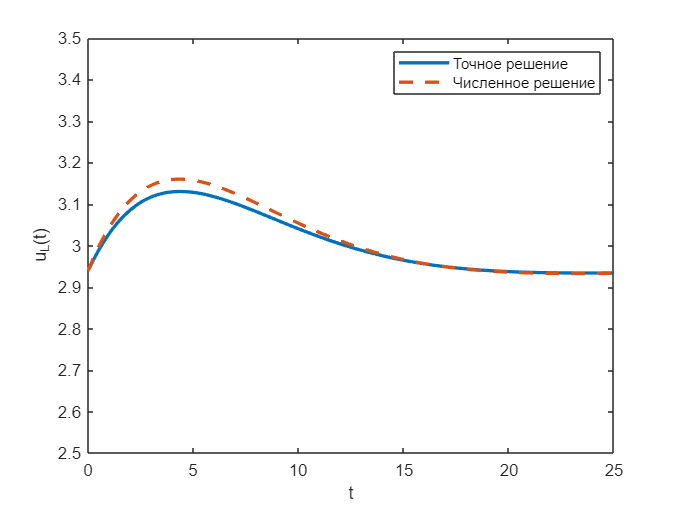

hold on
plot(xs, it_e, '--', 'linewidth', 2)
xlim([0, 25])
ylim([2.5, 3.5])
legend("Точное решение", "Численное решение")
%title("Решение уравнения состояния для L-элемента")
xlabel('t')
ylabel('u_L(t)')
hold off

Опкраторный метод

П 2. Дано

syms s U0
%Параметры сигнала
t_i = 4; %Время импульса
T = 4*t_i; %Период сигнала
%Параметры цепи
Z1 = 1;
Z2 = 24;
Z3 = 1;
Zn = 2;
Zl = 8*s;
Zc = 1/s;
I0 = 0;
Il = 0;
Uc = 0;
% U0 = 8/s-8/s*exp(-t_i*s);%Изображение входного сигнала

МКТ

A = [Z1+Z2, -Z2, 0; -Z2, Z2+Z3+Zl, -Zl; 0, -Zl, Zl+Zc+Zn]

$$A = \left(\begin{array}{ccc} 25 & -24 & 0\\ -24 & 8\,s+25 & -8\,s\\ 0 & -8\,s & 8\,s+\frac{1}{s}+2 \end{array}\right)$$

B = [U0; -Il*Zl; -I0*Zn+Il*Zl+Uc]

$$B = \left(\begin{array}{c} U_{0}\\ 0\\ 0 \end{array}\right)$$

Ik = linsolve(A, B); %Контурные токи
simplify(Ik)

$$ans = \left(\begin{array}{c} \frac{U_{0}\,\left(216\,s^{2}+58\,s+25\right)}{792\,s^{2}+298\,s+49}\\ \frac{24\,U_{0}\,\left(8\,s^{2}+2\,s+1\right)}{792\,s^{2}+298\,s+49}\\ \frac{192\,U_{0}\,s^{2}}{792\,s^{2}+298\,s+49} \end{array}\right)$$

In = Ik(3)+I0 %Ток через нагрузку

$$In = \frac{192\,U_{0}\,s^{2}}{792\,s^{2}+298\,s+49}$$

Un = simplify(In*Zn) %Напряжение нагрузки

$$Un = \frac{384\,U_{0}\,s^{2}}{792\,s^{2}+298\,s+49}$$

H = simplify(Un/U0) %Передаточная функция

$$H = \frac{384\,s^{2}}{792\,s^{2}+298\,s+49}$$

Нули и полюсы передаточной функции

zs = solve(384*s^2 == 0); %Нули передаточной функции
ps = solve(792*s^2+298*s+49 == 0); %Полюсы передаточной функции
vpa(zs, 4)

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

vpa(ps, 4)

$$ans = \left(\begin{array}{c} -0.1881-0.1627\,\mathrm{i}\\ -0.1881+0.1627\,\mathrm{i} \end{array}\right)$$

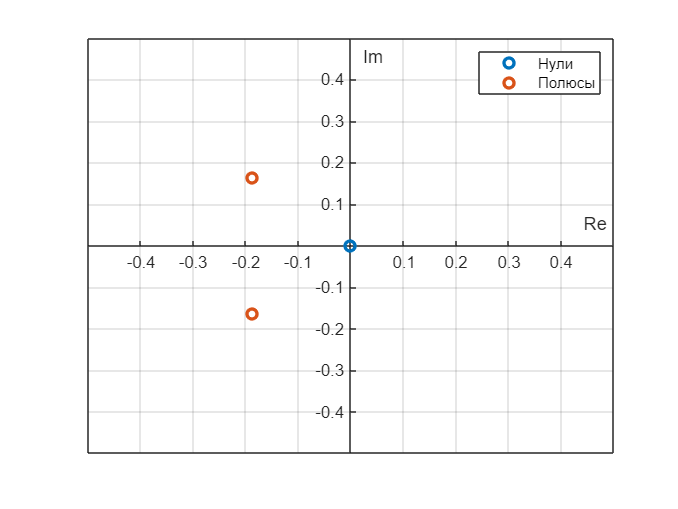

plot(real(zs), imag(zs), 'o', 'LineWidth', 2)
hold on
plot(real(ps), imag(ps), 'o', 'LineWidth', 2)
xlabel('Re')
ylabel('Im')
hold off
xlim([-0.5 0.5])
ylim([-0.5 0.5])
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
legend('Нули', 'Полюсы');
ax.XTick = [-0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000];

Переходная и импульсные характеристики

ht = ilaplace(H);
ht = vpa(simplify(ht), 4)

$$ht = 0.4848\,\delta (t)-0.1824\,{\mathrm{e}}^{-0.1881\,t}\,\left(\cos\left(0.1627\,t\right)-0.1457\,\sin\left(0.1627\,t\right)\right)$$

ht_1 = ilaplace(H/s);
ht_1 = vpa(simplify(ht_1), 4)

$$ht\_1 = 0.4848\,{\mathrm{e}}^{-0.1881\,t}\,\left(\cos\left(0.1627\,t\right)-1.156\,\sin\left(0.1627\,t\right)\right)$$

u0 = 8*heaviside(t)-8*heaviside(t-4); %Оригинал входного сигнала
U0 = laplace(u0) %Изображение входного сигнала

$$U0 = \frac{8}{s}-\frac{8\,{\mathrm{e}}^{-4\,s}}{s}$$

Un1 = simplify(H*U0) %Изображение напряжения нагрузки

$$Un1 = -\frac{384\,s\,\left(8\,{\mathrm{e}}^{-4\,s}-8\right)}{792\,s^{2}+298\,s+49}$$

un = ilaplace(Un1); %Оригинал напряжения нагрузки
un = vpa(un, 4)

$$un = 3.879\,{\mathrm{e}}^{-0.1881\,t}\,\left(\cos\left(0.1627\,t\right)-1.156\,\sin\left(0.1627\,t\right)\right)-3.879\,\mathrm{heaviside}\left(1.0\,t-4.0\right)\,{\mathrm{e}}^{0.7525-0.1881\,t}\,\left(\cos\left(0.1627\,t-0.6508\right)-1.156\,\sin\left(0.1627\,t-0.6508\right)\right)$$

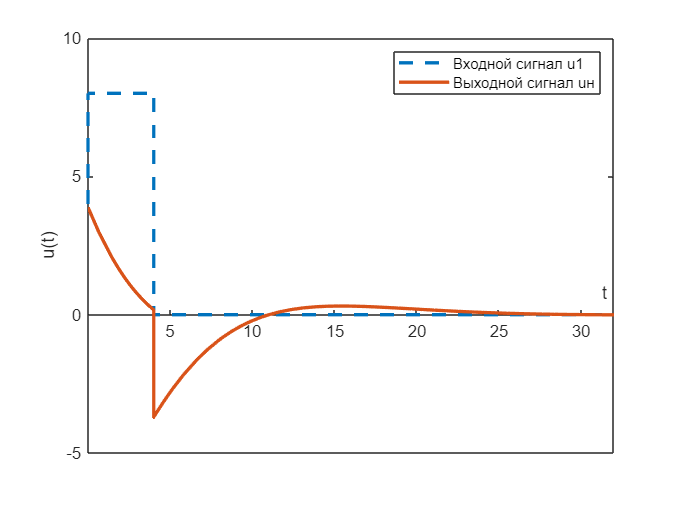

fplot(u0, '--', 'linewidth', 2)
hold on
fplot(un, '-', 'linewidth', 2)
hold off
legend('Входной сигнал u1', 'Выходной сигнал uн')
%title('Графики входного и выходного сигнала')
xlim([0 32])
ylim([-5 10])
xlabel('t')
ylabel('u(t)')
ax = gca;
ax.XAxisLocation = 'origin';

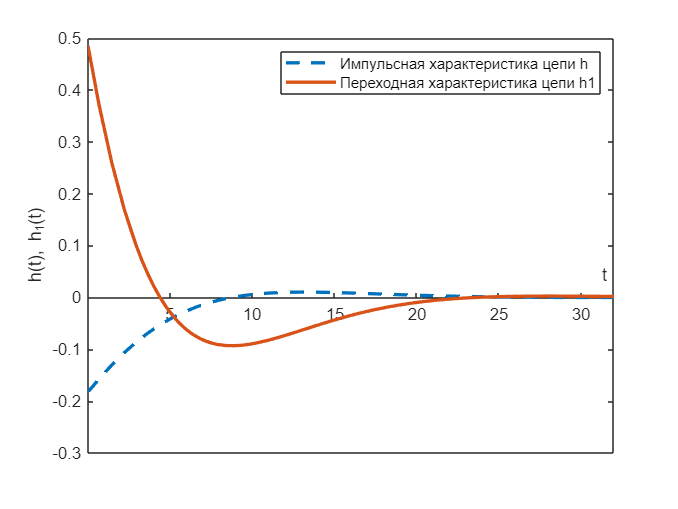

fplot(ht, '--', 'linewidth', 2)

hold on
fplot(ht_1, '-', 'linewidth', 2)
hold off
legend('Импульсная характеристика цепи h', 'Переходная характеристика цепи h1')
%title('Характеристики цепи')
xlim([0 32])
ylim([-0.3 0.5])
xlabel('t')
ylabel('h(t), h_1(t)')
ax = gca;
ax.XAxisLocation = 'origin';

3) Качественный анализ цепи частотным методом при апереодическом воздействии

3.1) АФХ, АЧХ, ФЧХ функций передачи цепи

Hs_U = H

$$Hs\_U = \frac{384\,s^{2}}{792\,s^{2}+298\,s+49}$$

Переход в частотную область

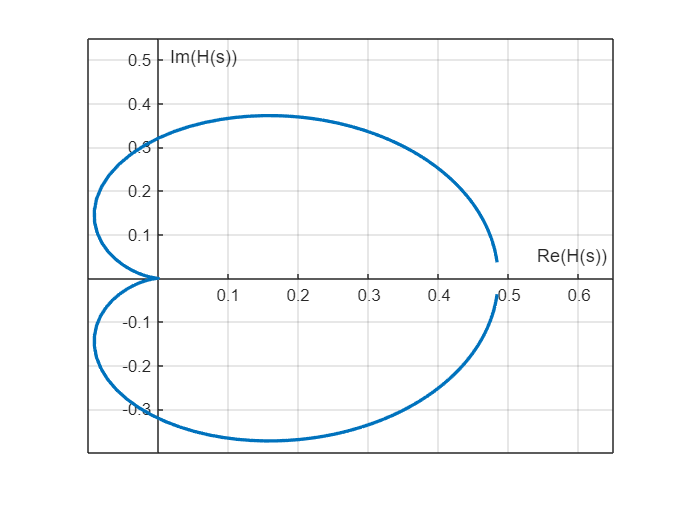

syms omega
Hjw_U = subs(Hs_U, s, 1i*omega);
fplot(real(Hjw_U), imag(Hjw_U), 'linewidth', 2)
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
grid on
ylabel('Im(H(s))')
xlabel('Re(H(s))')
xlim([-0.1 0.65])
ylim([-0.4 0.55])

Hjw_U

$$Hjw\_U = -\frac{384\,\omega^{2}}{-792\,\omega^{2}+298\,\omega \,\mathrm{i}+49}$$

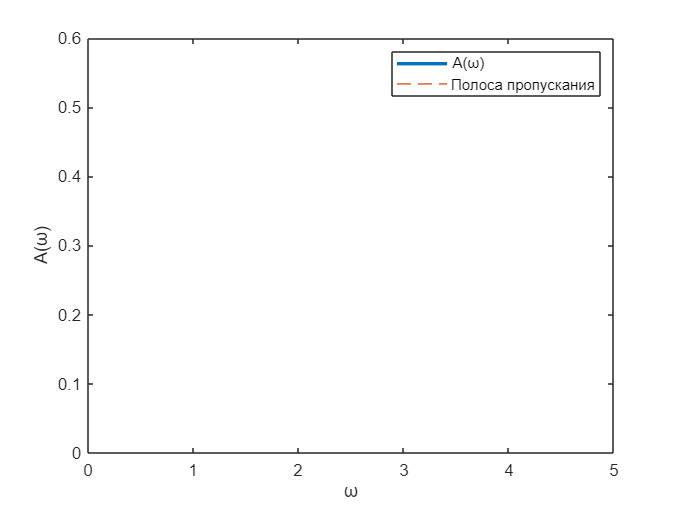

Re_Hjw_U = real(Hjw_U);
Im_Hjw_U = imag(Hjw_U);
A_U = sqrt(((304128*omega^4-18816*omega^2)^2+(114432*omega^3)^2)/((-792*omega^2+49)^2+(298*omega)^2));
A_U1 = sqrt(Re_Hjw_U^2+Im_Hjw_U^2);
A_U = abs(384*omega^2/sqrt((792*omega^2)^2+11188*omega^2+49^2));
pp = 0.707*384/792;
fplot(A_U, 'linewidth', 2)
hold on
fplot(pp, [0 5], '--')
xlim([0 5])
ylim([0 0.6])
legend('A(\omega)', 'Полоса пропускания')
ylabel('A(\omega)')
xlabel('\omega')
hold off

A_U

$$A\_U = \frac{384\,{\left|\omega \right|}^{2}}{\sqrt{\left|627264\,\omega^{4}+11188\,\omega^{2}+2401\right|}}$$

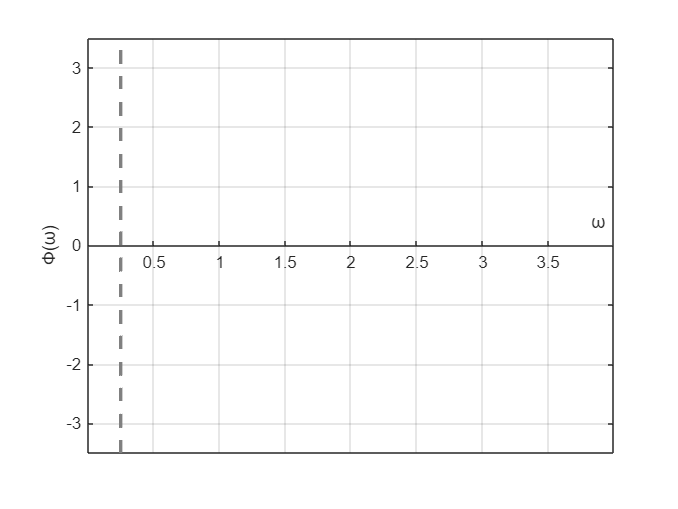

Fi_U = - atan(298*omega/(49-792*omega^2));
Fi_U1 = atan(298*omega/(49-792*omega^2));
Fi_U2 = pi + atan(298*omega/(49-792*omega^2));
fplot(Fi_U1, [0 0.248734], 'b-', 'linewidth', 2)
hold on
fplot(Fi_U2, [0.248734 4], 'b-', 'linewidth', 2)
xlim([0 4])
ylim([-3.5 3.5])
grid on
ylabel('Ф(\omega)')
xlabel('\omega')
ax = gca;
ax.XAxisLocation = 'origin';
hold off

Fi_U1

$$Fi\_U1 = -\mathrm{atan}\left(\frac{298\,\omega }{792\,\omega^{2}-49}\right)$$

Fi_U2

$$Fi\_U2 = \pi -\mathrm{atan}\left(\frac{298\,\omega }{792\,\omega^{2}-49}\right)$$

3.3 Спектры входного сигнала

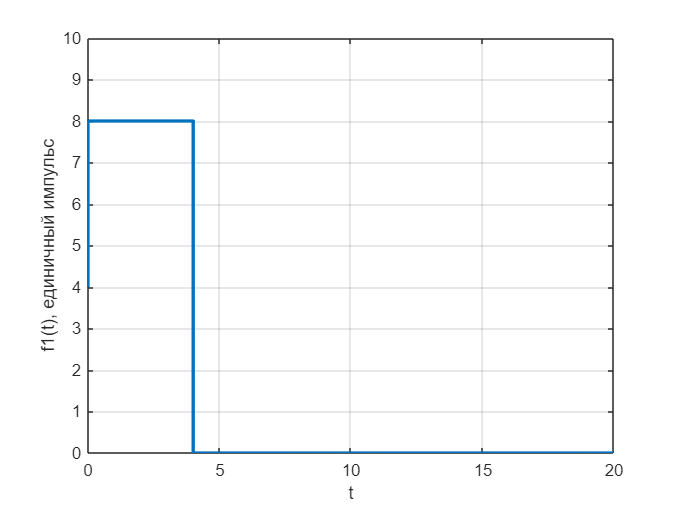

ft_1 = 8*heaviside(t) - 8*heaviside(t-4);
fplot(ft_1, 'LineWidth', 2)
xlim([0 20])
ylim([0 10])
ylabel('f1(t), единичный импульс')
xlabel('t')
grid on

ft_1

$$ft\_1 = 8\,\mathrm{heaviside}\left(t\right)-8\,\mathrm{heaviside}\left(t-4\right)$$

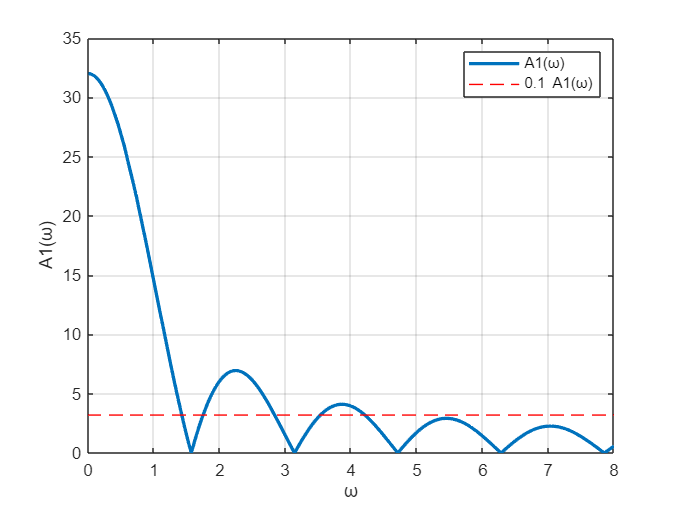

A1 = abs(16*sin(2*omega)/omega);
sw = 32*0.1;
fplot(A1, 'LineWidth', 2)
hold on
fplot(sw, 'r--')
xlim([0 8])
ylim([0 35])
legend('A1(\omega)', '0.1 A1(\omega)')
ylabel('A1(\omega)')
xlabel('\omega')
grid on
hold off

A1

$$A1 = \frac{16\,\left|\sin\left(2\,\omega \right)\right|}{\left|\omega \right|}$$

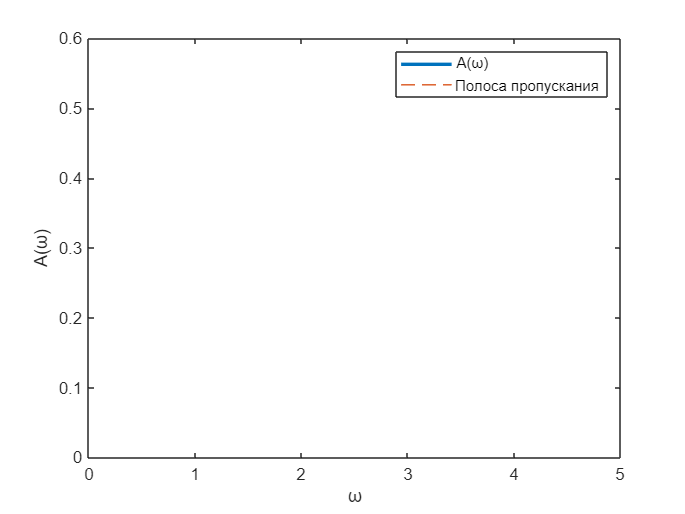

F1 = -2*omega;
t_trip = -10:0.1:10;
t_p = 0:0.01:50;
d_p = 0:10:50;
trip = -tripuls(t_p-5, 10, 1)*20;
y = pulstran(t_p, d_p, trip, 100);
plot(t_p, y, 'LineWidth', 2)
%fplot(F1, 'LineWidth', 2)
xlim([0 25])
ylim([-20 0])
ylabel('Ф1(t), единичный импульс')
xlabel('\omega')
ax = gca;
ax.XAxisLocation = 'origin';
grid on

F1

$$F1 = -2\,\omega$$

4. Анализ цепи частотным методом при периодическом воздействии

4.1 Дискретные спектры и ряд Фурье входного сигнала

Амплитудный спектр

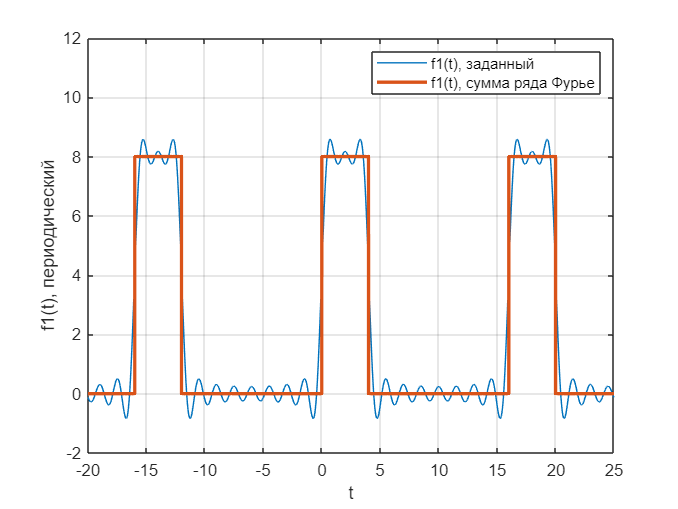

omg = 2*pi/T;
ks = 0:10;
omega_ks = omg.*ks;
A1_ks = [];
F1_ks = [];
A1_k = 32*2/T;
F1_k = 0;
k = 1;
f1_series = 0;
while (omg*(k-1) <= 4.3)
    % Дискретный амплитудный спектр
    A1_ks(k) = A1_k;
    % Дискретный фазовый спектр
    F1_ks(k) = F1_k;
    if k == 1
        f1_series = A1_k/2;
    else
        f1_series = f1_series + A1_ks(k)*cos(omg*(k-1)*t+F1_ks(k));
    end
    k = k+1;
    A1_k = subs(2/T*A1, omega, omg*(k-1));
    if subs(16*sin(2*omega)/omega, omg*(k-1)) >= 0
        F1_k = subs(F1, omega, omg*(k-1));
    else
        F1_k = subs(F1, omega, omg*(k-1))+pi;
    end
    A1_k = abs(subs(2/T*A1, omega, omg*(k-1)));
end
fplot(f1_series)
hold on
ft_1_series = 8*heaviside(t) - 8*heaviside(t-4) + 8*heaviside(t-16) - 8*heaviside(t-20) + 8*heaviside(t+16) - 8*heaviside(t+12);
fplot(ft_1_series, 'LineWidth', 2)
xlim([-20 25])
ylim([-2 12])
legend('f1(t), заданный', 'f1(t), сумма ряда Фурье')
ylabel('f1(t), периодический')
xlabel('t')
grid on
hold off

vpa(f1_series, 4)

$$ans = 1.2\,\cos\left(2.356-1.178\,t\right)+0.5145\,\cos\left(2.356-2.749\,t\right)+0.8488\,\cos\left(1.571-2.356\,t\right)+3.601\,\cos\left(0.7854-0.3927\,t\right)+2.546\,\cos\left(1.571-0.7854\,t\right)+0.7203\,\cos\left(0.7854-1.963\,t\right)+0.4001\,\cos\left(7.069-3.534\,t\right)+0.5093\,\cos\left(7.854-3.927\,t\right)+2.0$$

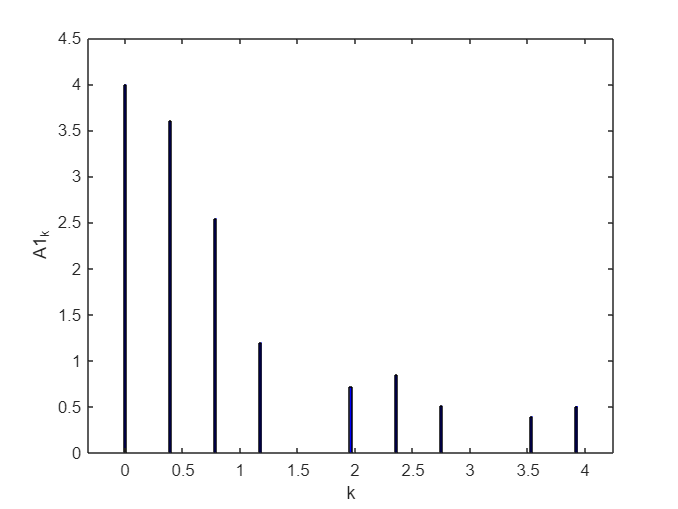

bar(omega_ks, A1_ks, 0.05, 'b')
ylabel('A1_k')
xlabel('k')
ylim([0 4.5])

A1_ks

A1_ks =     4.0000    3.6013    2.5465    1.2004         0    0.7203    0.8488    0.5145         0    0.4001    0.5093


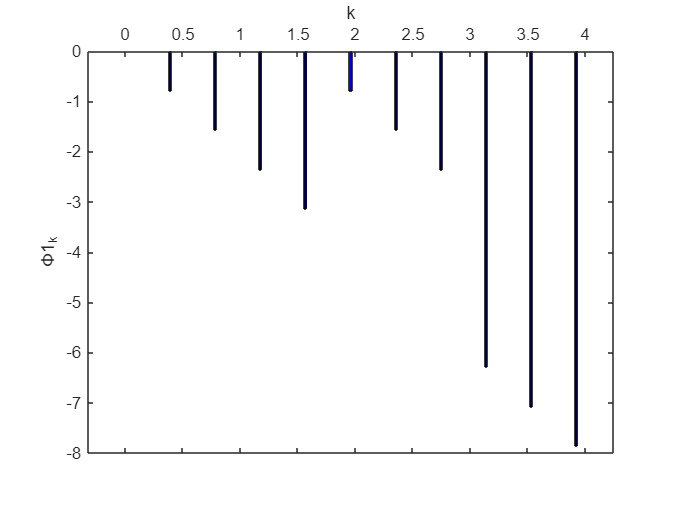

bar(omega_ks, F1_ks, 0.05, 'b')
ylabel('Ф1_k')
xlabel('k')
ax = gca;
ax.XAxisLocation = 'origin';

F1_ks

F1_ks =          0   -0.7854   -1.5708   -2.3562   -3.1416   -0.7854   -1.5708   -2.3562   -6.2832   -7.0686   -7.8540


4.3) Построение выходного сигнала

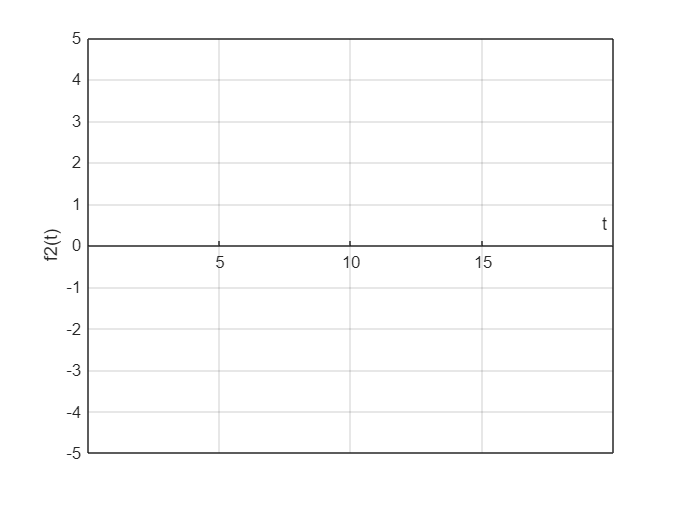

omg = 2*pi/T;
A2_ks = [];
F2_ks = [];
A2_k = 0;
F2_k = 0;
k = 1;
f2_series = 0;
while (k <= 11)
    % Дискретный амплитудный спектр
    A2_ks(k) = A2_k;
    % Дискретный фазовый спектр
    F2_ks(k) = F2_k;
    if k == 1
        f2_series = A2_ks(1)/2;
    else
        f2_series = f2_series + A2_ks(k)*cos(omg*(k-1)*t+F2_ks(k));
    end
    k = k+1;
    if k == 12
    break
    end
    A2_k = subs(A1_ks(k)*A_U, omega, omg*(k-1));
%     if A2_k > 0
        F2_k = F1_ks(k)+subs(Fi_U2, omega, omg*(k-1));
%     else
%         F2_k = subs(F1_ks(k-1)+Fi_U2, omega, omg*(k-1));
%     end
    A2_k = abs(subs(A1_ks(k)*A_U, omega, omg*(k-1)));
end
fplot(f2_series, 'linewidth', 2)
xlim([0 20])
ylim([-5 5])
grid on
ylabel('f2(t)')
xlabel('t')
ax = gca;
ax.XAxisLocation = 'origin';

vpa(f2_series, 4)

$$ans = 0.4109\,\cos\left(2.356\,t+1.411\right)+1.211\,\cos\left(0.7854\,t+1.082\right)+0.2491\,\cos\left(2.749\,t+0.6483\right)+0.1939\,\cos\left(3.534\,t-4.034\right)+1.545\,\cos\left(0.3927\,t+1.344\right)+0.5778\,\cos\left(1.178\,t+0.4628\right)+0.3484\,\cos\left(1.963\,t+2.164\right)+0.2468\,\cos\left(3.927\,t-4.808\right)$$

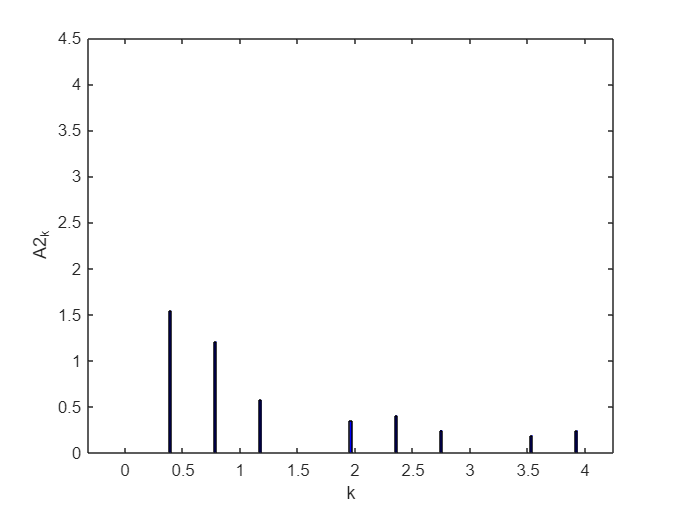

bar(omega_ks, A2_ks, 0.05, 'b')
ylabel('A2_k')
xlabel('k')
ylim([0 4.5])

A2_ks

A2_ks =          0    1.5454    1.2113    0.5778         0    0.3484    0.4109    0.2491         0    0.1939    0.2468


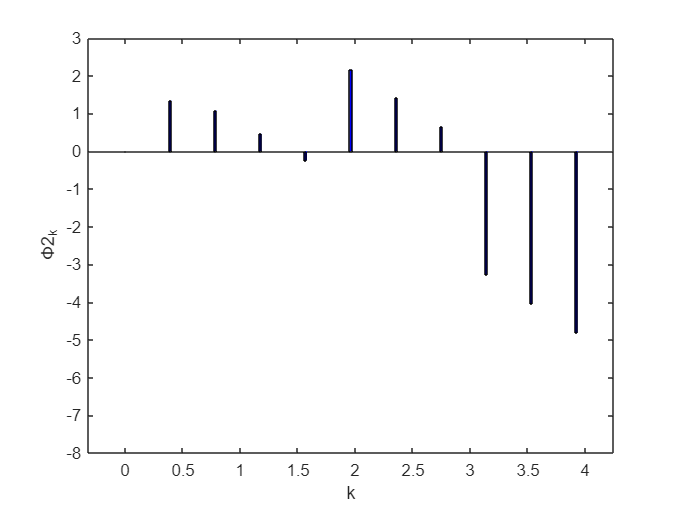

bar(omega_ks, F2_ks, 0.05, 'b')
ylabel('Ф2_k')
xlabel('k')
ylim([-8 3])


F2_ks

F2_ks =          0    1.3440    1.0815    0.4628   -0.2409    2.1638    1.4107    0.6483   -3.2615   -4.0336   -4.8083
